# Analiza harmoniczna sygnałów cz.2

### Mateusz Wójcik, 7.11.2024

Kontynuacja poprzedniego tematu laboratorium, dotyczącego analiz harmonicznej sygnałów. W tej części większą uwagę poświecono szeregom fouriera w postaci zespolonej niż w postaci trygonometrycznej. Ćwiczenie przeprowadzone na tych zajęciach stanowią domnknięcie najważniejszych informacji związazanych z tą tematyką. Na sam początek przystąpiono do użycia części wcześniejszego programu, by dalej przeprowadzać na nim operację. Zatem w pierwszym etapier wygenerowano sygnał prostokątny i współczynniki szeregu Fouriera w postaci zespolonej i trygonometrycznej.

clear, clc

## Generowanie sygnału trójkątnego

syms t t1 t2 offset x 

T0 = 1.0;		% okres
t1 = -0.5; 
t2 = t1+T0;
offset = T0/4;

f0 = 1/T0;		% czestotliwosc
w0 = 2*pi*f0;	% pulsacja

% granice całkowania
BND = [t1,t2] + offset; 

x = triangularPulse(t1,0,t2,t-offset)-0.5;

## Generowanie współczynników - postać wykładnicza

NT = 15;
X=[];
ind = -NT : NT;
for n = ind
    Xn = (1/T0)*int(x*exp(-1i*w0*n*t),t,BND);
    X(n + NT + 1) = Xn;
end

## Generowanie współczynników - postać trygonometryczna

n = 0:15;
a = arrayfun(@(n) 1/(t2-t1) * int(x*cos(w0*n*t), BND),n);
b = arrayfun(@(n) 1/(t2-t1) * int(x*sin(w0*n*t), BND),n);

## Zadanie 5

Na podstawie współczynników obliczonych we wcześniejszych zadaniach wykonano rekonstrukcje sygnału, korzystając z faktu przedstawienia sygnału w rozwinięciu w szereg Fourier'a:

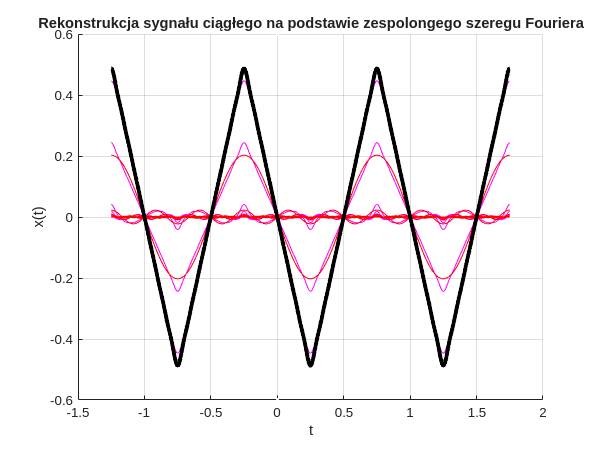

step = (BND(2) - BND(1))/1000;	
tt = [BND(1)-T0 : step: BND(2) + T0];
xx = zeros(1,length(tt));
xx =  xx + real(X(NT+1)); % skladowa stala
				
figure('Position', [100, 100, 800, 600])

hold on

plot(tt,xx,'m'); grid on, hold on;
plot([0,0],[-0.6,0.6],'w.')
xlabel('t'); ylabel('x(t)'); 
title('Rekonstrukcja sygnału ciągłego na podstawie zespolongego szeregu Fouriera')

				
for n = ind
    xx_n = real(X(n + NT + 1)*exp(-1i*w0*n*tt));
    xx = xx + xx_n;
    plot(tt,xx_n,'r'); plot(tt,xx,'m');

end

plot(tt,xx,'k','LineWidth',3);

hold off

pars_wave = int(x.^2,t,BND)/T0

$$pars\_wave = \frac{1}{12}$$

W celu obliczenia energii sygnału  w czasie skorzystano z **Twierdzenia Parsevsala:**


$$\frac{1}{T_0} \int_{t_1}^{t_1 + T_0} x^2(t)dt = \sum_{n =- \infty } ^{\infty} | X_n|^2$$


aproximed_wave = sum(abs(X).^2)

aproximed_wave = 0.0833


error_rel = eval(abs(pars_wave - aproximed_wave)/pars_wave)

error_rel = 3.9792e-05

Ograniczenie liczby elementów szeregu Fouriera w rekonstrukcji sygnału zmniejsza dokładność jego odtworzenia powodując jego odkształcenia od rzeczywistego sygnału. Szczególnie utracona zostaje informacja, w miejscach gdzie sygnał nie jest różniczkowalny, albo na odcinkach, gfzie pochodna wynosi zero. W tych miejscach odwzorowany sygnał im mniej zawiera elementów w rozwinięciu w szereg w tym mocniejsze oscylacje wpada.

## Zadanie 6

#### a) obliczanie wartości skutecznej

syms T0 x A

f = 1/T0

$$f = \frac{1}{T_{0}}$$

sk = eval(sqrt(1/T0 * int((A*sin(2* pi* x/T0))^2,0,T0)))

$$sk = \sqrt{\frac{A^{2}}{2}}$$

skd = eval(subs(sk, A, 1))

skd = 0.7071

Wynik zgadza się z tablicami matematyczni i potwierdza powszechnie stosowany w teorii obwodów wzór:

 
$$U_{sk} = \frac{U_m}{\sqrt{2}}$$


**b) Obiczenie wartości skutecznej sygnału **$x(t)$**:**

sk_triang_ideal = eval(sqrt(int(x^2,t1, t2)))

sk_triang_ideal = 0.2887

**c) Obliczenie wartości skutecznej na podstawie skończonej ilości wspólczynników szeregu Fouriera:**

sk_triang_from_coeffs = sqrt(trapz(real(xx(1001:2000).^2))/1000)

sk_triang_from_coeffs = 0.2883

abs(sk_triang_ideal-sk_triang_from_coeffs)/sk_triang_ideal

ans = 0.0014

Jak można zauważyć błąd względny pomiędzy wartością idealną, a przybliżoną za pomocą skończonej ilosći wyrazów nie różni się znacząco.

## Zadanie 7

n_val = 5:5:NT;
THD = zeros([1,length(n_val)]);
for n = n_val
    suma = sum(arrayfun(@(xxx) abs(xxx)^2,X((NT-n+1):(n+NT+1))));
    THD(n/5) = sqrt(suma - abs(X(NT+2))^2 - abs(X(NT))^2 )/ sqrt(abs(X(NT+2))^2 + abs(X(NT))^2);
end

THD

THD =     0.1181    0.1205    0.1210


Wartość wyliczona analitycznie wynosi natomiast:


$$\sqrt{ \frac{\pi^4}{96} -1} \approx 0,1211$$


Dla pierwszych pięciu współcznynników widoczna jest różnica, między wartością tablicową, a uzyskanąm natomiast wraz ze wzrostem ilości wyrazów szeregu Fouriera, wspóczynnik THD dąży do oczekiwanej wartości

# Zadanie domowe

Zadanie domowe polegało na odtworzeniu tych samych zadań (od 1 do 7) tylko dla innego sygnału - modyfkowanej sinusoidy. Wynki tych obliczeń przedstawiono w poniższych sekcjach

## Definiowanie funkcji modyfikowanej sinusoiudy

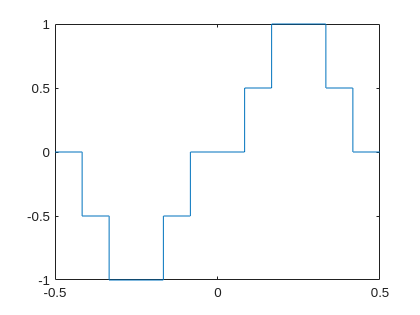

clear, clc, clf

syms t

T0 = 1;
f0 = 1/T0;
w0 = 2*pi*f0;
BND = [-0.5 0.5];

x1 = -rectangularPulse(-0.5 + 1/12, -1/12, t);
x2 = -rectangularPulse(-0.5 + 1/6, -1/6, t);
x3 = rectangularPulse(1/12, 0.5-1/12, t);
x4 = rectangularPulse(1/6, 0.5-1/6, t);

x =  0.5* (x1 + x2 + x3 + x4);
fplot(x, BND)

## Zadanie 1

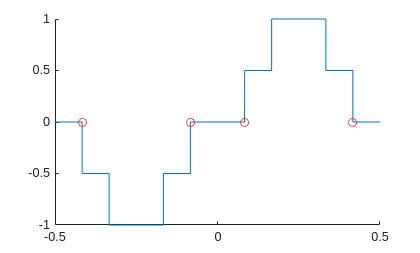

figure
hold on
fplot(x,BND);
plot([-5/12, -1/12, 1/12, 5/12], [0 0 0 0], "ro")
hold off

## Zadanie 2

NT = 15;
X=[];
ind = -NT : NT;
for n = ind
    Xn = (1/T0)*int(x*exp(-1i*w0*n*t),t,BND);
    X(n + NT + 1) = Xn;
end


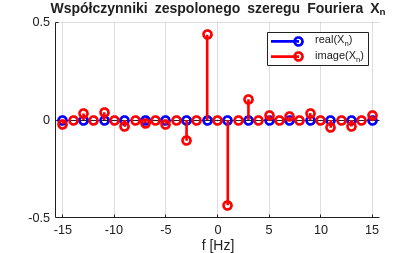

figure; hold on;
stem(ind*f0,real(X),'b','LineWidth',2);
xlabel('f [Hz]')
stem(ind*f0,imag(X),'r','LineWidth',2);
grid on

legend('real(X_n)','image(X_n)')
title('Współczynniki zespolonego szeregu Fouriera X_n')

## Zadanie 3

n = 0:15;
a = arrayfun(@(n) 1/T0 * int(x*cos(w0*n*t), BND),n);
b = arrayfun(@(n) 1/T0* int(x*sin(w0*n*t), BND),n);

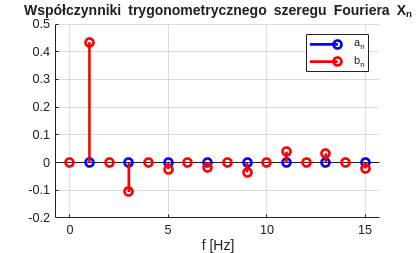

figure; hold on;
stem(n*f0,a,'b','LineWidth',2);
xlabel('f [Hz]')
stem(n*f0,b,'r','LineWidth',2);
grid on
legend('a_n','b_n','Location','NorthEast')
title('Współczynniki trygonometrycznego szeregu Fouriera X_n')

## Zad 4

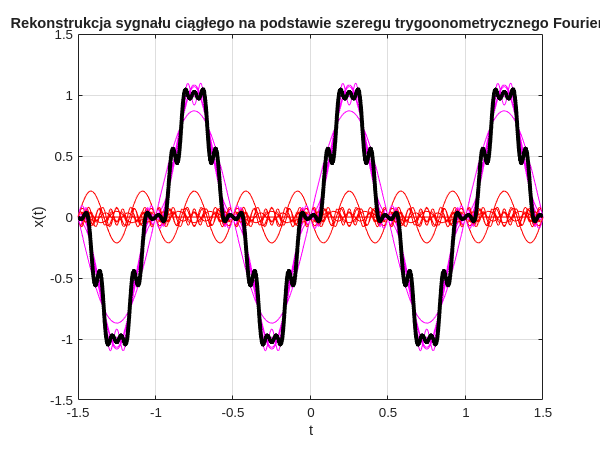

step = T0/1000;	
tt = [BND(1)-T0 :step: BND(2) + T0];
xx = zeros(1,length(tt));
xx =  xx + a(1); % skladowa stala
				
figure('Position', [100, 100, 800, 600])
plot(tt,xx,'m'); grid on, hold on;
plot([0,0],[-0.6,0.6],'w.')
xlabel('t'); ylabel('x(t)'); 

				
for n = 1 : NT
    xx_n = 2*(a(n+1)*cos(w0*n*tt) + b(n+1)*sin(w0*n*tt));
    xx = xx + xx_n;
    plot(tt,xx_n,'r'); plot(tt,xx,'m');
    title(sprintf('n = %d',n+1)); 
end

plot(tt,xx,'k','LineWidth',3);
title('Rekonstrukcja sygnału ciągłego na podstawie szeregu trygoonometrycznego Fouriera')
hold off

## Zadanie 5

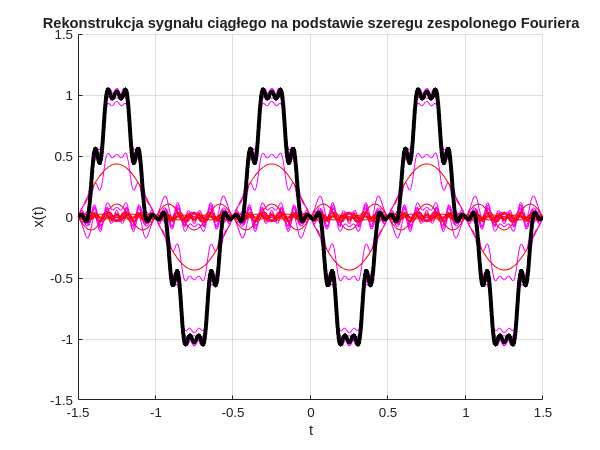

step = T0/1000;	
tt = [BND(1)-T0 : step: BND(2) + T0];
xxx = zeros(1,length(tt));
xxx =  xxx + real(X(NT+1)); % skladowa stala
				
figure('Position', [100, 100, 800, 600])
hold on
plot(tt,xxx,'m'); grid on, hold on;
plot([0,0],[-0.6,0.6],'w.')
xlabel('t'); ylabel('x(t)'); 
pause(0.5)
				
for n = ind
    xxx_n = real(X(n + NT + 1)*exp(-1i*w0*n*tt));
    xxx = xxx + xxx_n;
    plot(tt,xxx_n,'r'); plot(tt,xxx,'m');
    title(sprintf('n = %d',n+1));
end

plot(tt,xxx,'k','LineWidth',3);
title('Rekonstrukcja sygnału ciągłego na podstawie szeregu zespolonego Fouriera')
hold off

#### Obliczenie błędu aproksymacji

pars_wave = int(x.^2,t,BND)/T0 

$$pars\_wave = \frac{5}{12}$$

aproximed_wave = sum(abs(X).^2)

aproximed_wave = 0.4111

error_abs = eval(abs(pars_wave - aproximed_wave)/pars_wave)

error_abs = 0.0135

## Zad 6

signa_sk = eval(sqrt(int(x^2,BND)))

signa_sk = 0.6455

signal_sk_from_coeffs = eval(sqrt(trapz(real(xx(1001:2000).^2))/1000))

signal_sk_from_coeffs = 0.6411

## Zadanie 7

n_val = 5:5:NT;
THD = zeros([1,length(n_val)]);
for n = n_val
    suma = sum(arrayfun(@(xxx) abs(xxx)^2,X((NT-n+1):(n+NT+1))));
    THD(n/5) = sqrt(suma - abs(X(NT+2))^2 - abs(X(NT))^2 )/ sqrt(abs(X(NT+2))^2 + abs(X(NT))^2);
end

THD

THD =     0.2498    0.2655    0.2951


Rozważania dotyczącec takich sygnałów są bardzo pożyteczne, szczególnie, że w dzisiejszych czasach istnieje częsta potrzeba zamiany napięcia stałego na napięcie sinusoidalne. W związku z tym metody analizy harmonicznej pozwalają nam ocenić skuteczność sygnału, jak dobrze odwzorowywuje on przebieg sinusoidalny i inne ważne parametry. Daje to ogromne pole do optymalizacji procesów przekształcania energii i ograniczenia destrukcyjnie działających w obwodach trójfazowych, wyższych harmonicznych.

## Wnioski

Podczas laboratorium w dalszym stopniu zapoznawano się z matematycznym wstępem do teorii analizy harmonicznej sygnałów. Wszystkie obliczenia, które zostały przedstawione w instrukcji znalazły swoje przełożenie w trakcie tworzenia skryptu w Matlabie. Tym razem wykorzystano m.in.Twierdzenie Parsevala, czy porównywano wartść współczynnika THD w zależności od ilości uwaględnionych wspołczynników. Stworzenie uniwersalnego kodu, i testowanie go na powszechnie znaych sygnałach takich jak sygnał prostokątny, czy trójkątny pozwala nam jakościowo sprawdzić napisany program i zweryfikować wyniki z wartościami tablicowymi. Dzięki temu otrzymuje potem uniwersalny program, którym możemy badać różne inne sygnały, dla których wyliczenie wartości skutecznych, czy współczynnika THD może być bardzo trudne do wykonania analitycznie. 